# Example 5.13: Hougen-Watson Model with Constraints

Note: this script reproduces Example 5.13 (Section 5.4) of **Statistics for Chemical Engineers**: estimating the Hougen-Watson model with physical bounds on the parameters. Victor Z UW-Madison, 2020 hougen watson with constraints [https://www.mathworks.com/help/stats/rsmdemo.html](https://www.mathworks.com/help/stats/rsmdemo.html)

clc; clear all; close all hidden; format long e;

% S = load('reaction');
% X = S.reactants % experimental reactant concentrations
% y = S.rate % experimental reaction rates
% beta = S.beta % guess for parameters

datar=load('Data/hougenwatson.dat');
X=datar(:,1:3); %partial pressures
y=datar(:,4);   % reaction rate

[n,m]=size(X);

data.x=X;
data.y=y;
data.n=n;
data.m=m;

## Unconstrained estimation

solve unconstrained problem

beta=ones(5,1)*(-1);
options = optimoptions(@lsqnonlin,'Algorithm','trust-region-reflective','Display','iter');
[betahat,resnorm,residual,exitflag,output,lam,jacobian]...
    = lsqnonlin(@myfun,beta,[],[],options,data);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6            669.86                               36
     1         12            669.86              10               36      
     2         18            45.797             2.5              321      
     3         24            45.797               5              321      
     4         30            45.797            1.25              321      
     5         36           30.1376          0.3125              513      
     6         42           19.7189          0.3125             63.3      
     7         48           16.7594           0.625              258      
     8         54           7.64688            1.25              550      
     9         60           7.64688             2.5              550      
    10         66           4.29512           0.625              130      
    11         72           4.29512      


display(betahat)

betahat =     -4.047698691777216e+01
    -2.066705979205174e+00
    -1.389483137490412e+00
    -3.857107533457821e+00
    -3.757228305384309e-02


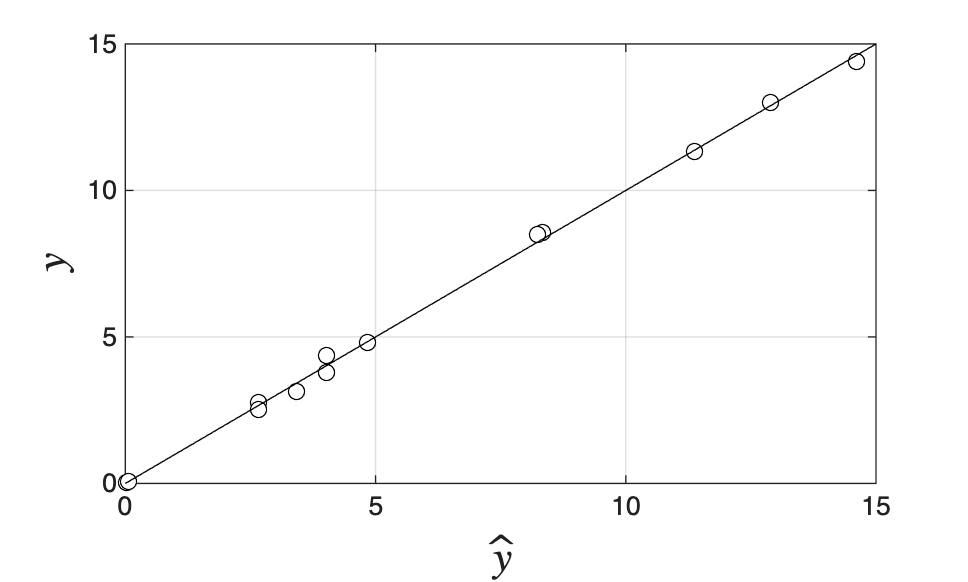


% model prediction
yhat=myfun(betahat,data)+data.y;

figure(2)
xx=linspace(0,15);
plot(yhat,data.y','blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black-')
xlabel('$\hat{y}$','Interpreter','latex','FontSize',16)
ylabel('$y$','Interpreter','latex','FontSize',16)
grid on
print -depsc ch5_hougen_fit_constraints.eps


% hessian is approximated as

H=full(jacobian'*jacobian);

% check eigenvalues

lambda=eigs(H)

lambda =      3.741734453818726e+04
     8.622597987432721e+01
     7.831731689812307e+00
     4.816196709018431e-01
     4.625615144035655e-08


## Constrained estimation

solve constrained problem

thetalb=zeros(5,1);
thetaub=ones(5,1)*2;
beta=ones(5,1)*(-1);
options = optimoptions(@lsqnonlin,'Algorithm','trust-region-reflective','Display','iter');
[betahat,resnorm,residual,exitflag,output,lambda,jacobian]...
    = lsqnonlin(@myfun,beta,thetalb,thetaub,options,data);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6           670.124                             35.8
     1         12           30.9359         1.99257              242      
     2         18           4.17972         0.30174              113      
     3         24           1.16823        0.463621             4.69      
     4         30          0.390014       0.0759201             12.5      
     5         36          0.306609         0.12538             0.46      
     6         42          0.304141      0.00963912           0.0063      
     7         48          0.304141        0.429529           0.0063      
     8         54          0.303335        0.107382            0.284      
     9         60          0.302115       0.0121584          0.00524      
    10         66           0.30167        0.107382            0.244      
    11         72          0.300504      


display(betahat)

betahat =      1.253087024374026e+00
     6.280102823875161e-02
     4.006549406004641e-02
     1.124583213364523e-01
     1.190893852270942e+00



% model prediction
yhat=myfun(betahat,data)+data.y;

% hessian is approximated as
H=full(jacobian'*jacobian)

H =      6.191205433456034e+02    -4.305485955154200e+03    -6.345588148806883e+03    -9.403906956626651e+02     9.998118336022785e+01
    -4.305485955154200e+03     3.779229374646223e+04     4.453103225964133e+04     4.721953154885662e+03    -4.341778907757558e+02
    -6.345588148806883e+03     4.453103225964133e+04     7.503605122344453e+04     9.325133630357548e+03    -6.630742685623417e+02
    -9.403906956626651e+02     4.721953154885662e+03     9.325133630357548e+03     2.149563223123406e+03    -1.937321959686706e+02
     9.998118336022785e+01    -4.341778907757558e+02    -6.630742685623417e+02    -1.937321959686706e+02     3.937552641661043e+01



% check eigenvalues

lambda=eigs(H)

lambda =      1.062930419949890e+05
     8.355590832411446e+03
     9.524038837389028e+02
     3.534196675803745e+01
     2.558489499692669e-02



% get covariance
e=yhat-y;
sigma2=var(e);

Cov=inv(H)*sigma2

Cov =      5.015078942144261e-01     2.517204164054920e-02     1.783538527825983e-02     4.320737923002691e-02    -4.829234045700438e-01
     2.517204164054920e-02     1.265974538087291e-03     8.933718456279171e-04     2.172542430692254e-03    -2.422339823406355e-02
     1.783538527825983e-02     8.933718456279171e-04     6.363746142290548e-04     1.530002687737309e-03    -1.719205484735754e-02
     4.320737923002691e-02     2.172542430692254e-03     1.530002687737309e-03     3.768482242591338e-03    -4.144892551960771e-02
    -4.829234045700438e-01    -2.422339823406355e-02    -1.719205484735754e-02    -4.144892551960771e-02     4.663119077515237e-01



Var=diag(Cov)

Var =      5.015078942144261e-01
     1.265974538087291e-03
     6.363746142290548e-04
     3.768482242591338e-03
     4.663119077515237e-01



function F=myfun(b,data)

b1=b(1);
b2=b(2);
b3=b(3);
b4=b(4);
b5=b(5);

x1=data.x(:,1);
x2=data.x(:,2);
x3=data.x(:,3);

y=(b1*x2-x3/b5)./(1+b2*x1+b3*x2+b4*x3);

F=y-data.y;

end

## Note

As in the book, the constraints keep the estimates physical, the Hessian is well conditioned, and the parameter variances are small.